clear, clc

--------------------
Robot: (3 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1         arm1         jnt1     revolute             base(0)   arm2(2)  
   2         arm2         jnt2     revolute             arm1(1)   arm3(3)  
   3         arm3         jnt3        fixed             arm2(2)   
--------------------


ans =   Axes (Primary) with properties:

             XLim: [-2.5000 2.5000]
             YLim: [-2.5000 2.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


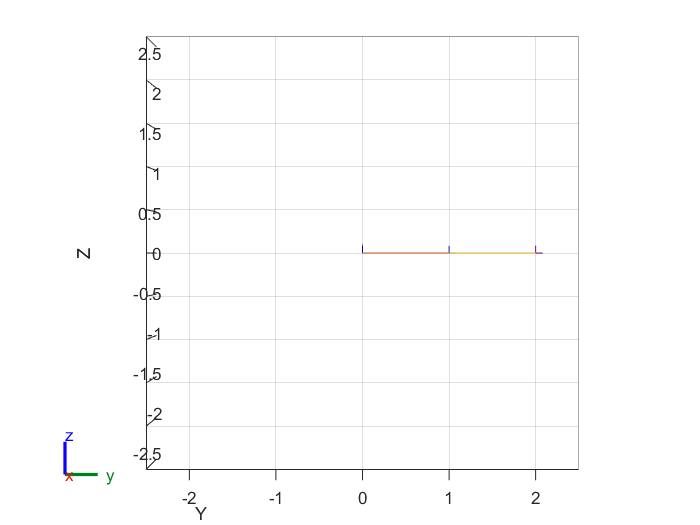

% Create robot
robot = create_robot_tree(1);

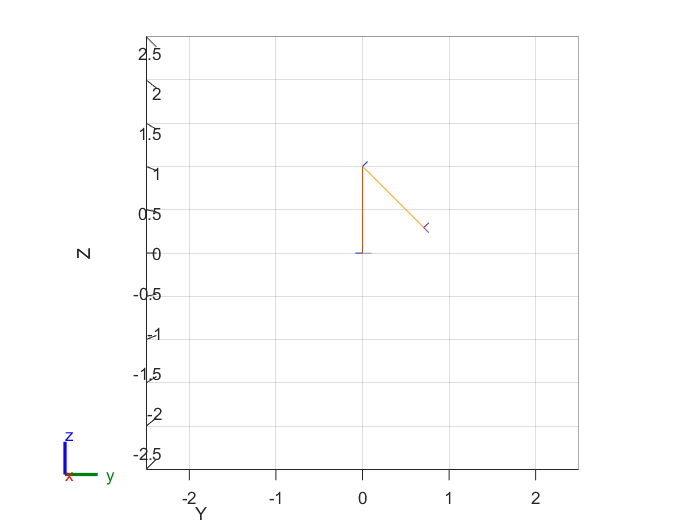

robot.Gravity = [0 0 -9.81];
config = homeConfiguration(robot);
pose = [pi/2; -3*pi/4];
show(robot,pose);
xlim([-.01,.01])
view(90,0)

% gui = interactiveRigidBodyTree(robot,"MarkerScaleFactor",0.25);

% Test simulation of nonlinear robot dynamics
u_test = @(t) 0*t;
tspan = [0,5];
x0 = [pose;0;0];
[t_test,x_test] = sim_robot(robot,u_test,x0,tspan);

% Animate response
q_test = x_test(:,1:2);
count = size(q_test,1);
rate = 0.01;
show(robot,q_test(1,:)');
xlim([-.01,.01])
view(90,0)

while true
    for i = 1:count
        show(robot,q_test(i,:)','PreservePlot',false);
        xlim([-.01,.01])
        view(90,0)
        drawnow
        pause(rate);
    end
    pause(0.5);
end % Need to manually stop execution here

% Create trajectory
ik = inverseKinematics('RigidBodyTree',robot);
% ignore orientation for now
weights = [0 0 0 1 1 1];

% Create waypoints:
x0 = [0 1 0.5];
xw = [0 0 2];
xf = [0 -1 1];
x = [x0; xw; xf];

% Timing parameter
r = 0.01;

% Equally spaced time points for each waypoint
n = size(x,1);
tf = 2;
tpts = linspace(0,tf,n);

% Solve for trajectory
[qt, qtd, qtdd, tpp] = create_traj(robot,weights,x,tpts,r,pose);
% Actually going to be interested in tpp, which can be evaluated
% at an arbitrary time

% Animate Trajectory
animate_traj(robot,qt,r) % Need to manually stop execution

% This block gets the A,B matrices as functitons of state
% q and input vars u
[q_ddot, q, u, vars] = robot_arm_dynamics();
[A,B,dq,du] = linearize_around_state(q_ddot,q,u);

A2 = subs(A,vars,[1,1,-9.81]);
B2 = subs(B,vars,[1,1,-9.81]);

ti = 0.75;

vars2 = [formula(q);formula(u)];
u_traj = @(t) [0;0]*t;
q_traj = @(t) ppval(tpp,t);
eval_vars = @(t) [q_traj(t);u_traj(t)];
eval_vars(ti);

At = @(t) eval_mat(A2,vars2,eval_vars,t);
Bt = @(t) eval_mat(B2,vars2,eval_vars,t);
Q = @(t) diag([1,1,0,0]);                            
R = @(t) eye(2);                         
S_tf = diag([1,1,0,0]); 
tspan = [0,3];
[time,K] = tvLQR(At,Bt,Q,R,S_tf,tspan);

time_f = flip(time);
K_f = flip(K,3); % These are in reverse order
Kt = @(t) piecewise_gains(K_f,time_f,t)'; % 2x4 gain matrix?

x0 = [qt(:,1);0;0];
[t_sim,x_sim] = sim_robot_lqr(robot,Kt,q_traj,x0,[0,tf]);

r = 0.01;
q_sim = x_sim(:,1:2)';
animate_traj(robot,q_sim,r)